# FUck FUck FUUKC

## p1

mu_M = 42828.314258067; %km^3/s^2
R_M = 3397;
a_ph = 9376;
a_de = 23458;
TA = deg2rad(240);
phi = deg2rad(120);
TOF_hr = 15;

r1 = a_ph;
r2 = a_de;
c = sqrt(r1^2+r2^2-2*r1*r2*cos(phi))
s = 1/2*(r1+r2+c)
TOFpar = 1/3*sqrt(2/mu_M)*(s^1.5+(s-c)^1.5)
TOFpar/(3600)
a_min = s/2
alpha0 = 2*asin(sqrt(s/(2*a_min)))
beta0 = 2*asin(sqrt((s-c)/(2*a_min)))
TOFmin = sqrt(a_min^3/mu_M)*((alpha0-sin(alpha0))-(beta0-sin(beta0)))
TOFmin/3600

a_range = linspace(a_min,2*a_min,100);
type = 22; % 2B
tof_vec = lambert_eqn(mu_M,a_range,s,c,type);
figure
plot(a_range,tof_vec)


TOF = TOF_hr*3600;
lambert_eqn(mu_M,a_min,s,c,type)
a0 = [a_min 3*a_min];
a = sol_lam_eqn(mu_M,TOF,s,c,a0,type,1)
sol_lam_eqn(mu_M,TOF,s,c,a0,type)

[TOF, alpha, beta] = lambert_eqn(mu_M,a,s,c,type)
rad2deg([alpha, beta])

p = 4*a*(s-r1)*(s-r2)*sin(([alpha+beta alpha-beta])/2).^2/c^2
p = max(p)
e = sqrt(1-p/a)
epsilon = -mu_M/(2*a)
rp = a*(1-e)
ra = a*(1+e)

v_dep = sqrt(2*mu_M/r1-mu_M/a)
v_arr = sqrt(2*mu_M/r2-mu_M/a)

theta_a_dep = -acos(p/(r1*e)-1/e)
rad2deg(theta_a_dep)

theta_a_arr = -acos(p/(r2*e)-1/e)
rad2deg(theta_a_arr)

gamma_dep = -acos(sqrt(mu_M*p)/(r1*v_dep))
rad2deg(gamma_dep)
gamma_arr = -acos(sqrt(mu_M*p)/(r2*v_arr))
rad2deg(gamma_arr)

figure
plot_orbit_3d(0,a_ph,0,0,0);
plot_orbit_3d(0,a_de,0,0,0);
rot = abs(-pi/2-theta_a_dep);
plot_orbit_3d(e,a,0,-rot,0,[theta_a_dep 2*pi+theta_a_arr]);
grid off
plot(0,0,'ok')
view([0,0,1])

v1 = sqrt(mu_M/r1)
dv_dep = sqrt(v1^2+v_dep^2-2*v1*v_dep*cos(abs(gamma_dep)))
v1_vnb = [v1 0 0]'
dgamma_dep = gamma_dep-0;
v_dep_vnb = v_dep*[sin(pi/2-dgamma_dep) 0 cos(pi/2-dgamma_dep)]'
dv_dep_vnb = v_dep_vnb-v1_vnb
norm(dv_dep_vnb)
alpha_dep = acos(dot(dv_dep_vnb,v1_vnb)/(dv_dep*v1))
rad2deg(alpha_dep)
rad2deg(atan2(dv_dep_vnb(3),dv_dep_vnb(1)))

v2 = sqrt(mu_M/r2)
dv_arr = sqrt(v2^2+v_arr^2-2*v2*v_arr*cos(abs(gamma_arr)))
v_arr_vnb = [v_arr 0 0]'
dgamma_arr = 0-gamma_arr;
v2_vnb = v2*[sin(pi/2-dgamma_arr) 0 cos(pi/2-dgamma_arr)]'
dv_arr_vnb = v2_vnb-v_arr_vnb
norm(dv_arr_vnb)
alpha_arr = acos(dot(dv_arr_vnb,v_arr_vnb)/(dv_arr*v_arr))
rad2deg(alpha_arr)
rad2deg(atan2(dv_arr_vnb(3),dv_arr_vnb(1)))

dv_total = dv_arr+dv_dep

n_ph = sqrt(mu_M/a_ph^3)
n_de = sqrt(mu_M/a_de^3)
period_ph = 2*pi/n_ph/3600
period_de = 2*pi/n_de/3600
phase_angle = TA-n_de*TOF
rad2deg(phase_angle)
ts = 2*pi/(n_ph-n_de)/3600

## P2

mu_E = 398600.4415;
a_E = 149597898;
a_M = 227944135;
R_E = 6378.1363;
mu_S = 132712440017.99;
mu_M = 42828.314258067;
R_M = 3397;

TOF = 160*24*3600

TOF = 13824000

r1 = a_E;
r2 = a_M;
TA = 120;
phi = deg2rad(TA)

phi = 2.0944

c = sqrt(r1^2+r2^2-2*r1*r2*cos(phi))

c = 3.2930e+08

s = 1/2*(r1+r2+c)

s = 3.5342e+08

a_min = 1/2*s

a_min = 1.7671e+08

TOFpar = 1/3*sqrt(2/mu_S)*(s^1.5-(s-c)^1.5)

TOFpar = 8.4443e+06

TOFpar/(3600*24)

ans = 97.7346


alpha0 = 2*asin(sqrt(s/(2*a_min)))

alpha0 = 3.1416

beta0 = 2*asin(sqrt((s-c)/(2*a_min)))

beta0 = 0.5286

rad2deg(beta0)

ans = 30.2884


TOFmin = sqrt(a_min^3/mu_S)*((alpha0-sin(alpha0))-(beta0-sin(beta0)))

TOFmin = 2.0101e+07

TOFmin/(3600*24)

ans = 232.6504

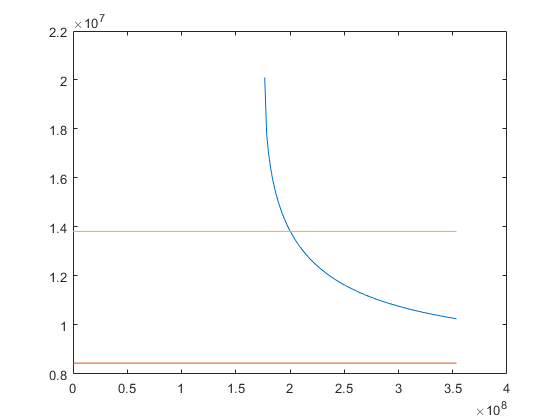

a_range = linspace(a_min,2*a_min,100);
type = 11; % 1A
tof_vec = lambert_eqn(mu_S,a_range,s,c,type);
figure
plot(a_range,tof_vec)
hold on
plot([0,a_range(end)],[TOFpar TOFpar])
plot([0,a_range(end)],[TOF TOF])

a0 = [a_min 3*a_min];
a = sol_lam_eqn(mu_S,TOF,s,c,a0,11,0)

ct = 48

a = 2.0028e+08

[TOF_check, alpha, beta] = lambert_eqn(mu_S,a,s,c,11)

TOF_check = 1.3824e+07

alpha = 2.4413

beta = 0.4959

TOF-TOF_check

ans = 4.0978e-08

rad2deg([alpha, beta])

ans =   139.8778   28.4108


p = 4*a*(s-r1)*(s-r2)*sin([alpha+beta alpha-beta]/2).^2/c^2

p = 	1.0e+08 *

    1.8697    1.2904


p = max(p)

p = 1.8697e+08

e = sqrt(1-p/a)

e = 0.2577

epsilon = -mu_S/(2*a)

epsilon = -331.3247

rp = a*(1-e)

rp = 1.4866e+08

ra = a*(1+e)

ra = 2.5189e+08


v_dep = sqrt(2*mu_S/r1-mu_S/a)

v_dep = 33.3408

v_arr = sqrt(2*mu_S/r2-mu_S/a)

v_arr = 22.4005


theta_a_dep = acos(p/(r1*e)-1/e)

theta_a_dep = 0.2482

rad2deg(theta_a_dep)

ans = 14.2201


theta_a_arr = acos(p/(r2*e)-1/e)

theta_a_arr = 2.3426

rad2deg(theta_a_arr)

ans = 134.2201


gamma_dep = acos(sqrt(mu_S*p)/(r1*v_dep))

gamma_dep = 0.0506

rad2deg(gamma_dep)

ans = 2.8999

gamma_arr = acos(sqrt(mu_S*p)/(r2*v_arr))

gamma_arr = 0.2215

rad2deg(gamma_arr)

ans = 12.6903

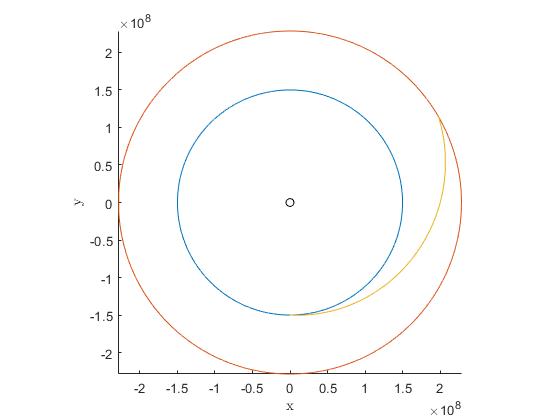

figure
plot_orbit_3d(0,a_E,0,0,0);
plot_orbit_3d(0,a_M,0,0,0);
rot = abs(pi/2+theta_a_dep);
plot_orbit_3d(e,a,0,-rot,0,[theta_a_dep theta_a_arr]);
grid off
plot(0,0,'ok')
view([0,0,1])

v1 = sqrt(mu_S/r1)

v1 = 29.7847

dv_dep = sqrt(v1^2+v_dep^2-2*v1*v_dep*cos(abs(gamma_dep)))

dv_dep = 3.8973

v1_vnb = [v1 0 0]'

v1_vnb =    29.7847
         0
         0


dgamma_dep = gamma_dep-0;
v_dep_vnb = v_dep*[sin(pi/2-dgamma_dep) 0 cos(pi/2-dgamma_dep)]'

v_dep_vnb =    33.2981
         0
    1.6867


dv_dep_vnb = v_dep_vnb-v1_vnb

dv_dep_vnb =     3.5134
         0
    1.6867


norm(dv_dep_vnb)

ans = 3.8973

alpha_dep = acos(dot(dv_dep_vnb,v1_vnb)/(dv_dep*v1))

alpha_dep = 0.4476

rad2deg(alpha_dep)

ans = 25.6451

rad2deg(atan2(dv_dep_vnb(3),dv_dep_vnb(1)))

ans = 25.6451


v2 = sqrt(mu_S/r2)

v2 = 24.1291

dv_arr = sqrt(v2^2+v_arr^2-2*v2*v_arr*cos(abs(gamma_arr)))

dv_arr = 5.4217

v_arr_vnb = [v_arr 0 0]'

v_arr_vnb =    22.4005
         0
         0


dgamma_arr = 0-gamma_arr;
v2_vnb = v2*[sin(pi/2-dgamma_arr) 0 cos(pi/2-dgamma_arr)]'

v2_vnb =    23.5397
         0
   -5.3007


dv_arr_vnb = v2_vnb-v_arr_vnb

dv_arr_vnb =     1.1392
         0
   -5.3007


norm(dv_arr_vnb)

ans = 5.4217

alpha_arr = acos(dot(dv_arr_vnb,v_arr_vnb)/(dv_arr*v_arr))

alpha_arr = 1.3591

rad2deg(alpha_arr)

ans = 77.8703

rad2deg(atan2(dv_arr_vnb(3),dv_arr_vnb(1)))

ans = -77.8703


dv_total = dv_arr+dv_dep

dv_total = 9.3190

v_inf_E = dv_dep

v_inf_E = 3.8973

ah_E = mu_E/v_inf_E^2

ah_E = 2.6243e+04

rph_E = 1000+R_E;
eh_E = rph_E/ah_E+1

eh_E = 1.2811

delta_E= asin(1/eh_E)*2

delta_E = 1.7911

rad2deg(delta_E)

ans = 102.6220

vph = sqrt(2*mu_E/rph_E+mu_E/ah_E)

vph = 11.1013

vc_E = sqrt(mu_E/rph_E)

vc_E = 7.3501

vph-vc_E

ans = 3.7511


v_inf_M = dv_arr

v_inf_M = 5.4217

ah_M = mu_M/v_inf_M^2

ah_M = 1.4570e+03

rph_M = 500+R_M;
eh_M = rph_M/ah_M+1

eh_M = 3.6747

delta_M = asin(1/eh_M)*2

delta_M = 0.5512

rad2deg(delta_M)

ans = 31.5822

vph_M = sqrt(2*mu_M/rph_M+mu_M/ah_M)

vph_M = 7.1677

sqrt(mu_M/rph_M)

ans = 3.3151

## P3

mu_E = 398600.4415;
a_E = 149597898;
a_M = 227944135;
R_E = 6378.1363;
mu_S = 132712440017.99;
mu_M = 42828.314258067;
R_M = 3397;

TOF = 92*24*3600

TOF = 7948800

r1 = a_E;
r2 = a_M;
TA = 120;
phi = deg2rad(TA)

phi = 2.0944

c = sqrt(r1^2+r2^2-2*r1*r2*cos(phi))

c = 3.2930e+08

s = 1/2*(r1+r2+c)

s = 3.5342e+08

a_min = 1/2*s

a_min = 1.7671e+08

TOFpar = 1/3*sqrt(2/mu_S)*(s^1.5-(s-c)^1.5)

TOFpar = 8.4443e+06

TOFpar/(3600*24)

ans = 97.7346

a_range = linspace(2*a_min,10*a_min)

a_range = 	1.0e+09 *

    0.3534    0.3677    0.3820    0.3963    0.4105    0.4248    0.4391    0.4534    0.4677    0.4819    0.4962    0.5105    0.5248    0.5391    0.5533    0.5676    0.5819    0.5962    0.6105    0.6247    0.6390    0.6533    0.6676    0.6819    0.6961    0.7104    0.7247    0.7390    0.7533    0.7675    0.7818    0.7961    0.8104    0.8246    0.8389    0.8532    0.8675    0.8818    0.8960    0.9103    0.9246    0.9389    0.9532    0.9674    0.9817    0.9960    1.0103    1.0246    1.0388    1.0531


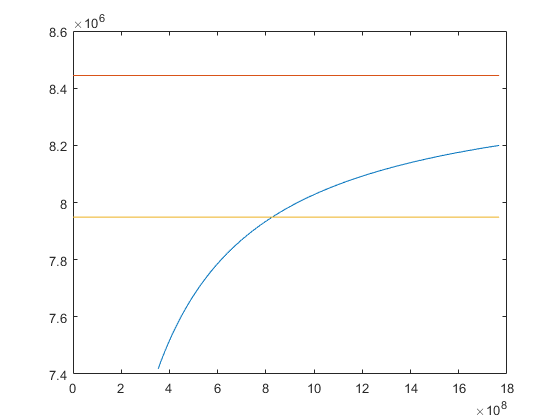

type = 13; % 1H
tof_vec = lambert_eqn(mu_S,a_range,s,c,type);
figure
plot(a_range,tof_vec)
hold on
plot([0,a_range(end)],[TOFpar TOFpar])
plot([0,a_range(end)],[TOF TOF])


a0 = [6e8 10e8];
a = sol_lam_eqn(mu_S,TOF,s,c,a0,type,1)

ct = 12

a = 8.2606e+08

[TOF_check, alpha, beta] = lambert_eqn(mu_S,a,s,c,type)

TOF_check = 7.9488e+06

alpha = 0.8949

beta = 0.2411

TOF-TOF_check

ans = 1.1176e-08

rad2deg([alpha, beta])

ans =    51.2724   13.8128


p = 4*a*(s-r1)*(s-r2)*sinh([alpha+beta alpha-beta]/2).^2/c^2

p = 	1.0e+08 *

    2.7962    0.8629


p = max(p)

p = 2.7962e+08

e = sqrt(p/a+1)

e = 1.1569

epsilon = -mu_S/(2*a)

epsilon = -80.3289

rp = a*(e-1)

rp = 1.2964e+08


v_dep = sqrt(2*mu_S/r1+mu_S/a)

v_dep = 43.9876

v_arr = sqrt(2*mu_S/r2+mu_S/a)

v_arr = 36.4017


theta_a_dep = -acos(p/(r1*e)-1/e)

theta_a_dep = -0.7208

rad2deg(theta_a_dep)

ans = -41.3007


theta_a_arr = acos(p/(r2*e)-1/e)

theta_a_arr = 1.3736

rad2deg(theta_a_arr)

ans = 78.6993


gamma_dep = -acos(sqrt(mu_S*p)/(r1*v_dep))

gamma_dep = -0.3878

rad2deg(gamma_dep)

ans = -22.2211

gamma_arr = acos(sqrt(mu_S*p)/(r2*v_arr))

gamma_arr = 0.7464

rad2deg(gamma_arr)

ans = 42.7637

figure
plot_orbit_3d(0,a_E,0,0,0);
plot_orbit_3d(0,a_M,0,0,0);
rot = abs(pi/2+theta_a_dep);
plot_orbit_3d(e,a,0,0,0,[theta_a_dep theta_a_arr]);
grid off
plot(0,0,'ok')
view([0,0,1])

v1 = sqrt(mu_S/r1)

v1 = 29.7847

dv_dep = sqrt(v1^2+v_dep^2-2*v1*v_dep*cos(abs(gamma_dep)))

dv_dep = 19.9081

v1_vnb = [v1 0 0]'

v1_vnb =    29.7847
         0
         0


dgamma_dep = gamma_dep-0;
v_dep_vnb = v_dep*[sin(pi/2-dgamma_dep) 0 cos(pi/2-dgamma_dep)]'

v_dep_vnb =    40.7207
         0
  -16.6353


dv_dep_vnb = v_dep_vnb-v1_vnb

dv_dep_vnb =    10.9361
         0
  -16.6353


norm(dv_dep_vnb)

ans = 19.9081

alpha_dep = acos(dot(dv_dep_vnb,v1_vnb)/(dv_dep*v1))

alpha_dep = 0.9892

rad2deg(alpha_dep)

ans = 56.6791

rad2deg(atan2(dv_dep_vnb(3),dv_dep_vnb(1)))

ans = -56.6791


v2 = sqrt(mu_S/r2)

v2 = 24.1291

dv_arr = sqrt(v2^2+v_arr^2-2*v2*v_arr*cos(abs(gamma_arr)))

dv_arr = 24.8519

v_arr_vnb = [v_arr 0 0]'

v_arr_vnb =    36.4017
         0
         0


dgamma_arr = 0-gamma_arr;
v2_vnb = v2*[sin(pi/2-dgamma_arr) 0 cos(pi/2-dgamma_arr)]'

v2_vnb =    17.7146
         0
  -16.3831


dv_arr_vnb = v2_vnb-v_arr_vnb

dv_arr_vnb =   -18.6871
         0
  -16.3831


norm(dv_arr_vnb)

ans = 24.8519

alpha_arr = acos(dot(dv_arr_vnb,v_arr_vnb)/(dv_arr*v_arr))

alpha_arr = 2.4218

rad2deg(alpha_arr)

ans = 138.7587

rad2deg(atan2(dv_arr_vnb(3),dv_arr_vnb(1)))

ans = -138.7587


dv_total = dv_arr+dv_dep

dv_total = 44.7599

v_inf_E = dv_dep

v_inf_E = 19.9081

ah_E = mu_E/v_inf_E^2

ah_E = 1.0057e+03

rph_E = 1000+R_E;
eh_E = rph_E/ah_E+1

eh_E = 8.3361

delta_E= asin(1/eh_E)*2

delta_E = 0.2405

rad2deg(delta_E)

ans = 13.7796

vph = sqrt(2*mu_E/rph_E+mu_E/ah_E)

vph = 22.4584

vc_E = sqrt(mu_E/rph_E)

vc_E = 7.3501

vph-vc_E

ans = 15.1083


v_inf_M = dv_arr

v_inf_M = 24.8519

ah_M = mu_M/v_inf_M^2

ah_M = 69.3447

rph_M = 500+R_M;
eh_M = rph_M/ah_M+1

eh_M = 57.1975

delta_M = asin(1/eh_M)*2

delta_M = 0.0350

rad2deg(delta_M)

ans = 2.0035

vc_M = sqrt(mu_M/rph_M)

vc_M = 3.3151

vph_M = sqrt(2*mu_M/rph_M+mu_M/ah_M)

vph_M = 25.2902

## P4

mu_E = 398600.4415;
a_E = 149597898;
a_M = 227944135;
R_E = 6378.1363;
mu_S = 132712440017.99;
mu_M = 42828.314258067;

TOF = 175*24*3600

TOF = 15120000

r1 = a_E;
r2 = a_M;
TA = deg2rad(120);
phi = TA;
c = sqrt(r1^2+r2^2-2*r1*r2*cos(phi))

c = 3.2930e+08

s = 1/2*(r1+r2+c)

s = 3.5342e+08

a_min = 1/2*s

a_min = 1.7671e+08

TOFpar = 1/3*sqrt(2/mu_S)*(s^1.5-(s-c)^1.5)

TOFpar = 8.4443e+06

TOFpar/(3600*24)

ans = 97.7346


alpha0 = 2*asin(sqrt(s/(2*a_min)))

alpha0 = 3.1416

beta0 = 2*asin(sqrt((s-c)/(2*a_min)))

beta0 = 0.5286

rad2deg(beta0)

ans = 30.2884


TOFmin = sqrt(a_min^3/mu_S)*((alpha0-sin(alpha0))-(beta0-sin(beta0)))

TOFmin = 2.0101e+07

TOFmin/(3600*24)

ans = 232.6504

a_range = linspace(a_min,2*a_min,100);
if TA < pi
    type = 10;
elseif TA > pi
    type = 20;
end

if TOF<TOFpar
    type = type+3;
else
    if TOF<TOFmin
        type = type+1;
    else
        type = type+2;
    end
end
type

type = 11

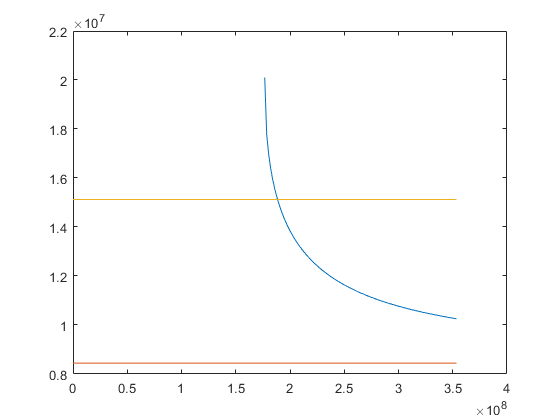


tof_vec = lambert_eqn(mu_S,a_range,s,c,type);
figure
plot(a_range,tof_vec)
hold on
plot([0,a_range(end)],[TOFpar TOFpar])
plot([0,a_range(end)],[TOF TOF])

a0 = [a_min 3*a_min];
a = sol_lam_eqn(mu_S,TOF,s,c,a0,type,0)

ct = 48

a = 1.8857e+08

[TOF_check, alpha, beta] = lambert_eqn(mu_S,a,s,c,type)

TOF_check = 1.5120e+07

alpha = 2.6347

beta = 0.5114

TOF-TOF_check

ans = -9.4995e-08

rad2deg([alpha, beta])

ans =   150.9563   29.2987


p = 4*a*(s-r1)*(s-r2)*sin([alpha+beta alpha-beta]/2).^2/c^2

p = 	1.0e+08 *

    1.7789    1.3563


if type == 11 || type == 22
    p = max(p)
elseif type == 12 || type == 21
    p = min(p)
elseif type == 13
    p = max(p)
elseif type == 23
    p = min(p)
end

p = 1.7789e+08


e = sqrt(1-p/a)

e = 0.2379

epsilon = -mu_S/(2*a)

epsilon = -351.8983

rp = a*(1-e)

rp = 1.4370e+08

ra = a*(1+e)

ra = 2.3343e+08


v_dep = sqrt(2*mu_S/r1-mu_S/a)

v_dep = 32.7179

v_arr = sqrt(2*mu_S/r2-mu_S/a)

v_arr = 21.4624


theta_a_dep = -acos(p/(r1*e)-1/e)

theta_a_dep = -0.6519

rad2deg(theta_a_dep)

ans = -37.3526


theta_a_arr = -acos(p/(r2*e)-1/e)

theta_a_arr = -2.7463

rad2deg(theta_a_arr)

ans = -157.3526


gamma_dep = -acos(sqrt(mu_S*p)/(r1*v_dep))

gamma_dep = -0.1208

rad2deg(gamma_dep)

ans = -6.9216

gamma_arr = -acos(sqrt(mu_S*p)/(r2*v_arr))

gamma_arr = -0.1169

rad2deg(gamma_arr)

ans = -6.6955

v1 = sqrt(mu_S/r1)

v1 = 29.7847

dv_dep = sqrt(v1^2+v_dep^2-2*v1*v_dep*cos(abs(gamma_dep)))

dv_dep = 4.7757

v1_vnb = [v1 0 0]'

v1_vnb =    29.7847
         0
         0


dgamma_dep = gamma_dep-0;
v_dep_vnb = v_dep*[sin(pi/2-dgamma_dep) 0 cos(pi/2-dgamma_dep)]'

v_dep_vnb =    32.4794
         0
   -3.9429


dv_dep_vnb = v_dep_vnb-v1_vnb

dv_dep_vnb =     2.6947
         0
   -3.9429


norm(dv_dep_vnb)

ans = 4.7757

alpha_dep = acos(dot(dv_dep_vnb,v1_vnb)/(dv_dep*v1))

alpha_dep = 0.9713

rad2deg(alpha_dep)

ans = 55.6495

rad2deg(atan2(dv_dep_vnb(3),dv_dep_vnb(1)))

ans = -55.6495


v2 = sqrt(mu_S/r2)

v2 = 24.1291

dv_arr = sqrt(v2^2+v_arr^2-2*v2*v_arr*cos(abs(gamma_arr)))

dv_arr = 3.7650

v_arr_vnb = [v_arr 0 0]'

v_arr_vnb =    21.4624
         0
         0


dgamma_arr = 0-gamma_arr;
v2_vnb = v2*[sin(pi/2-dgamma_arr) 0 cos(pi/2-dgamma_arr)]'

v2_vnb =    23.9646
         0
    2.8133


dv_arr_vnb = v2_vnb-v_arr_vnb

dv_arr_vnb =     2.5022
         0
    2.8133


norm(dv_arr_vnb)

ans = 3.7650

alpha_arr = acos(dot(dv_arr_vnb,v_arr_vnb)/(dv_arr*v_arr))

alpha_arr = 0.8439

rad2deg(alpha_arr)

ans = 48.3494

rad2deg(atan2(dv_arr_vnb(3),dv_arr_vnb(1)))

ans = 48.3494


dv_total = dv_arr+dv_dep

dv_total = 8.5408

figure
plot_orbit_3d(0,a_E,0,0,0);
plot_orbit_3d(0,a_M,0,0,0);
rot = abs(pi/2+theta_a_dep);
plot_orbit_3d(e,a,0,-rot,0,[theta_a_dep theta_a_arr]);
grid off
plot(0,0,'ok')
view([0,0,1])

v_inf_E = dv_dep
ah_E = mu_E/v_inf_E^2
rph_E = 1000;
eh_E = rph_E/ah_E+1
delta_E= asin(1/eh_E)*2
rad2deg(delta_E)
vph = sqrt(2*mu_E/rph_E+mu_E/ah_E)
vc_E = sqrt(mu_E/rph_E)
vph-vc_E

v_inf_M = dv_arr
ah_M = mu_M/v_inf_M^2
rph_M = 500;
eh_M = rph_M/ah_M+1
delta_M = asin(1/eh_M)*2
rad2deg(delta_M)
vph_M = sqrt(2*mu_M/rph_M+mu_M/ah_M)